% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

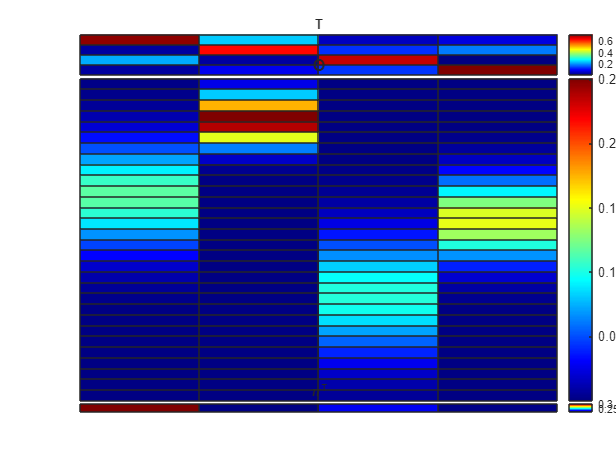

k = 4;
d = 30;

options.method = "random_no_offset";
options.lambda = 3;

[T, O, pi, k, d] = generateHMM(k, d, 1, options);

figure();
subplot(k+d+1, k, 1:k*k);
h = heatmap(T, 'CellLabelColor','none',Colormap=jet());
h.Title = 'T';  
h.YDisplayLabels = repmat(' ', k, 1);                                   
h.XDisplayLabels = repmat(' ', k, 1);

subplot(k+d+1, k, (k*k+1):(k*k+d*k));
h = heatmap(O, 'CellLabelColor','none', Colormap=jet());
h.Title = 'O';
h.YDisplayLabels = repmat(' ', d, 1);                                   
h.XDisplayLabels = repmat(' ', k, 1);

subplot(k+d+1, k, (k*k+d*k+1):(k*k+d*k+k));
h = heatmap(pi, 'CellLabelColor','none', Colormap=jet());
h.Title = '\pi^T';
h.YDisplayLabels = repmat(' ', 1, 1);                                   
h.XDisplayLabels = repmat(' ', k, 1);

Generate an observational sequence based on the defined HMM3, 4



D = {};
D{1} = Stochasticize(O * diag(pi) * T' * inv(diag(T * pi')));
D{2} = O;
D{3} = Stochasticize(O * T);
P3_inf = cpdgen(D)/k;


T_seq = 1e6;

Taug = [0, pi; zeros(k, 1), T'];
Oaug = [zeros(1, d); O'];
[seq,states] = hmmgenerate(T_seq, Taug, Oaug);

tic
[P3_n, convergence] = estimate_joint_prob(seq, d, P3_inf);
toc

Elapsed time is 0.016052 seconds.


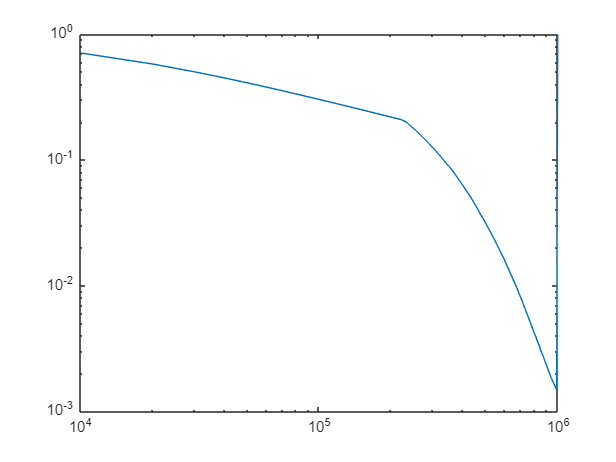


% alpha = 1e-6;
% P3_n = laplacian_smoothing_mle(P3_n, alpha);

figure()
loglog(linspace(0, T_seq, length(convergence)), convergence)


tic
[Uhat, output] = cpd(P3_inf, k);
toc

Elapsed time is 0.052334 seconds.


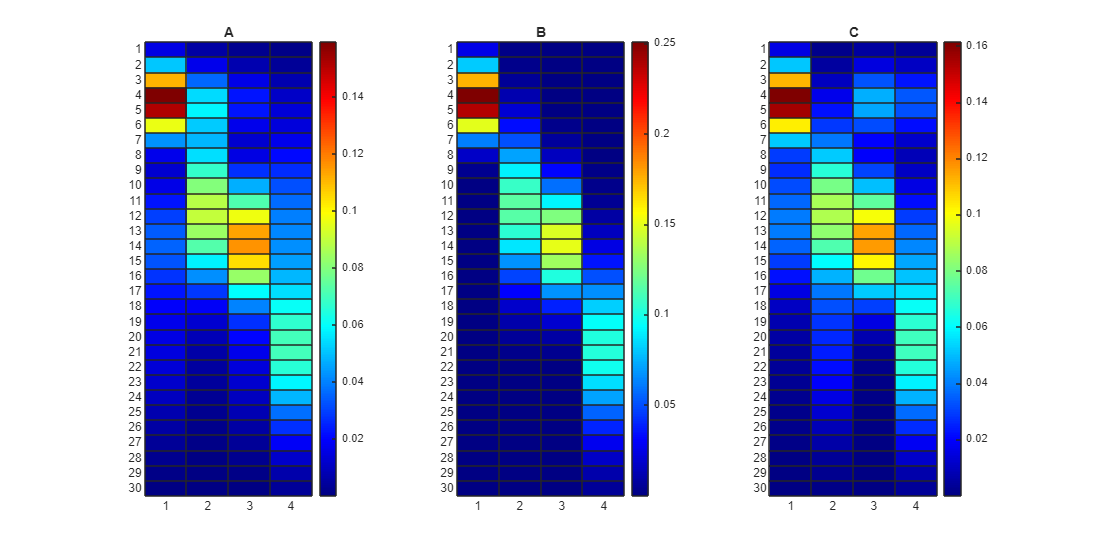


B1 = Stochasticize(Uhat{1});
B2 = Stochasticize(Uhat{2});
B3 = Stochasticize(Uhat{3});


% k_A = krushkal_rank(B1);
% k_B = krushkal_rank(B2);
% k_C = krushkal_rank(B3);
% 
% if((k_A + k_B + k_C) >= (2 * k + 2))
%     display("Decomposition is unique according to krushkal rank theorem");
% else
%     display("Decomposition is NOT unique according to krushkal rank theorem");
% end

NormalizeAndPlotHM(B1, B2, B3);

[T_hat, O_hat, pi_hat] = FactorMatrices2HMM({B1, B2, B3});
[T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hat, pi_hat');


plotHMMError(T, T_hat, O, O_hat, pi, pi_hat'); 

Error using plotHMMError
Too many input arguments.